# Neurotech 2020 - Hypothesis testing walk-through

General guidelines for approaching this are based on: 

[https://docs.google.com/document/d/1un3ktVI5TszrWPqvOtlkFC-b8ghoYDOqR86uorV5A_Y/edit?usp=sharing](https://docs.google.com/document/d/1un3ktVI5TszrWPqvOtlkFC-b8ghoYDOqR86uorV5A_Y/edit?usp=sharing)

## Data Set: Mouse in a Maze

Background: Mice tend to avoid open spaces (turns out these are dangerous for prey). Scientists study mice using an elevated plus-maze:

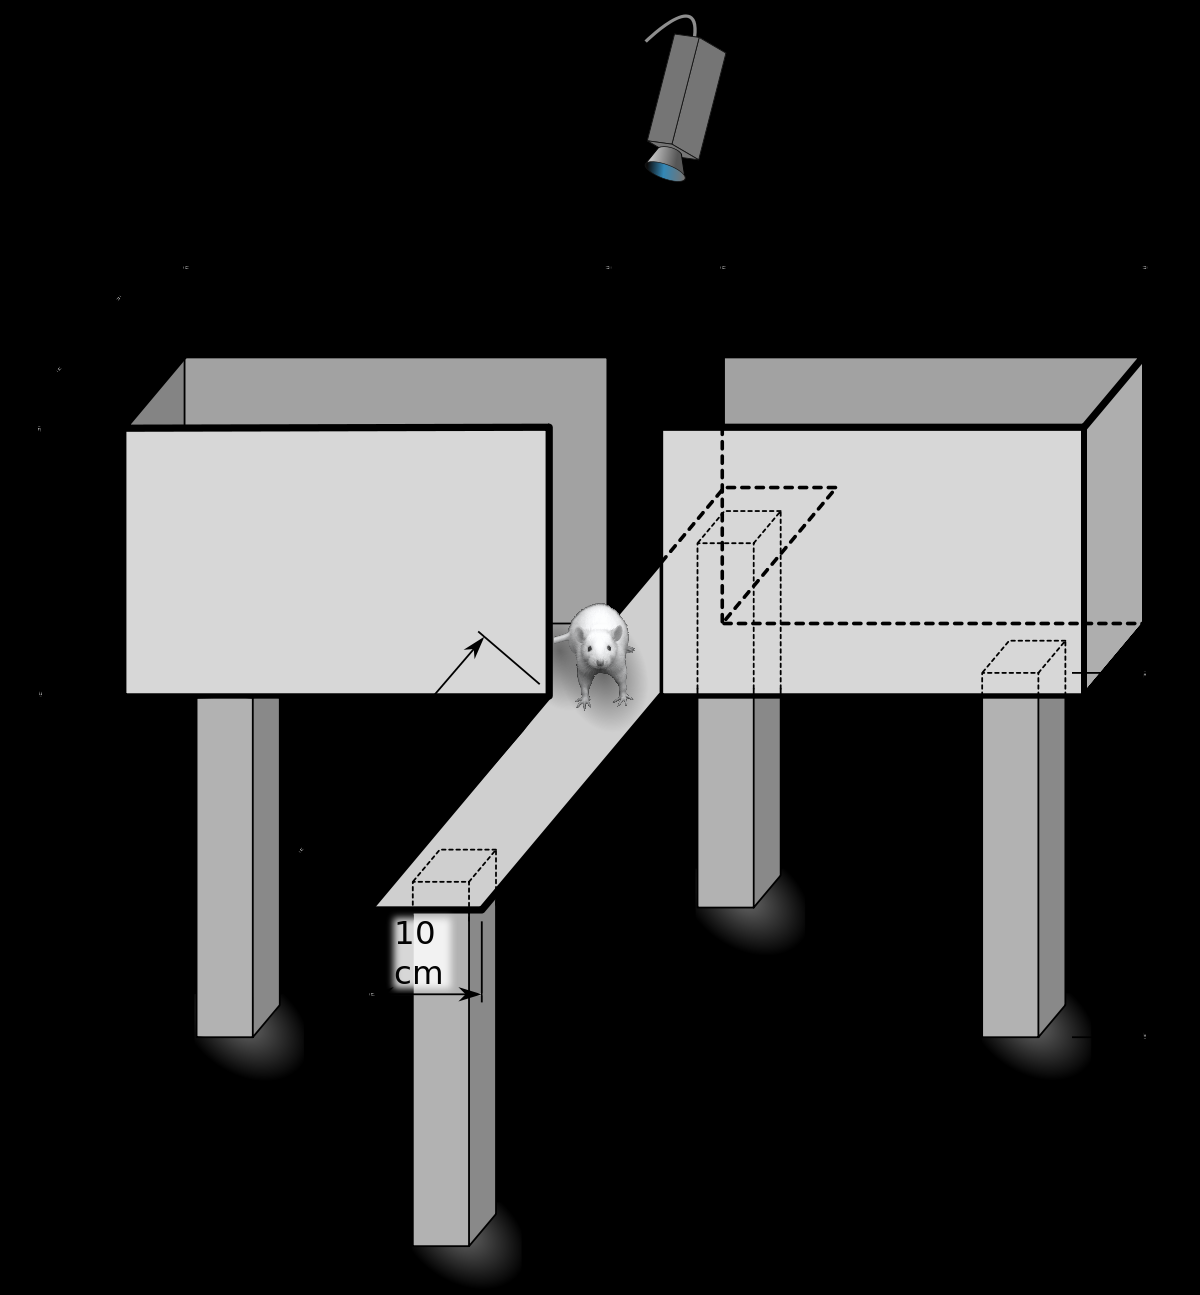

One common this to look at is the percentage of time that mice spend in the open (exposed) arm of the maze, which is considered a proxy measure of anxiety.  If mice were indifferent to the open vs closed arm of the maze, then we would expect to observe the mouse in the open arm of the maze approximately 50% of the time. 

These data give the percentage of time that each of 15 mice spent in the open arm. Use the process above to investigate how this relates to the hypothesized 50% (if indifferent). 

load('mouse.mat');

#### Plot the data (boxplot, histogram, scatterplot, binned histogram, whatever makes sense)

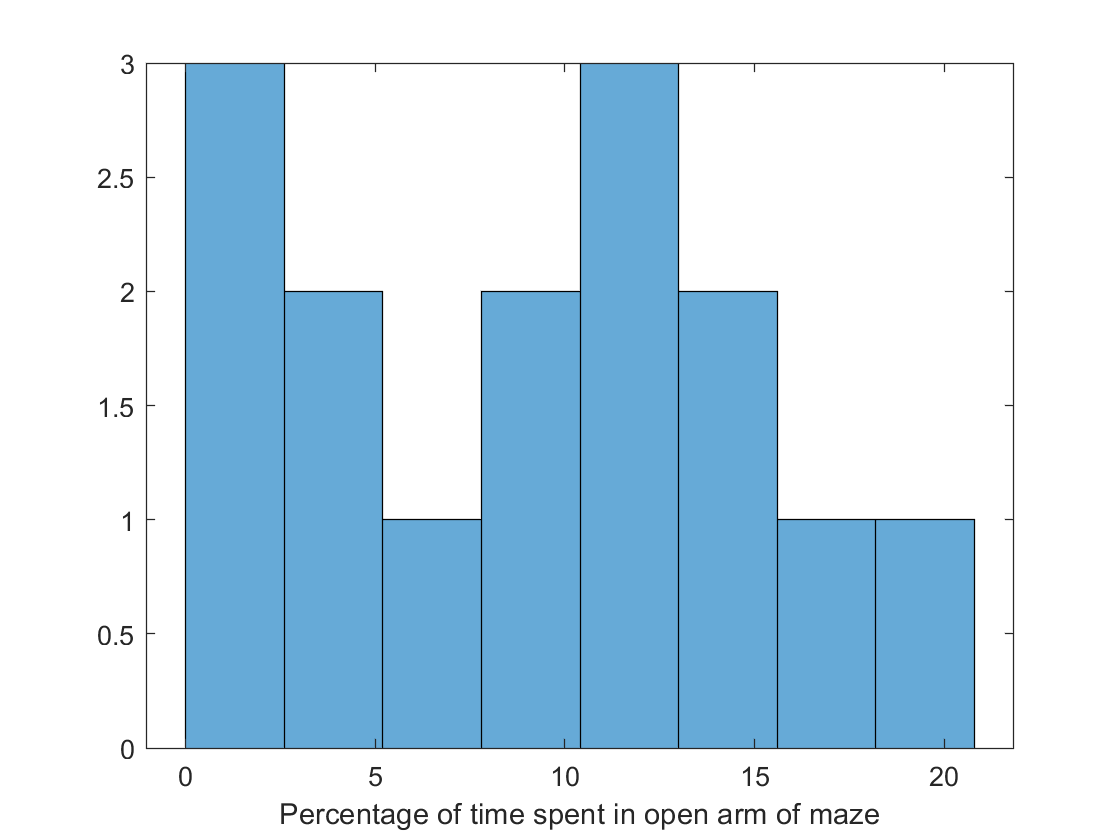

histogram(openarm,8); xlabel('Percentage of time spent in open arm of maze')

### Make sure that the data are complete, or determine/justify what to do with incomplete data (e.g, remove points, estimate replacements).

This is a really simple data set. All of the numbers make sense. They are in a range of 0 to 100. No need to remove any data here.

### State what you are trying to answer (e.g., what is the difference between values for category A and B, and is this meaningful). 

- Note how these data are organized (e.g, the values are in vector "values" and the categories are represented by the strings 'A' and 'B' in the vector "group"). Understand if these variables are categorical, discrete, continuous, counts, measurements, etc.

- It may be helpful to either sketch out or actually generate a plot to illustrate your question (create final version in step 6).

This one is a really simple case. We just have one variable (openarm), which corresponds to the percentage of time spent in the open arm of the maze. In this example, we're trying figure out if mice spend less time in the open arm of the maze. From visual inspection, it seems like the answer is yes (perhaps an obvious yes, since our histogram shows that each mouse spent less than 50% of its time in the open arm). However, we want to be able to support this with some statistical testing. 

One statistics question we may want ask is: is our observed data improbable, given our null hypothesis? In our case, our observed data are the percentage of time spent in the open part of the maze by each mouse. For our null hypothesis, we might choose 50%, since this is a number that would represent a model of the world where mice don't care if the space is open or closed (they just randomly wander around, ambivalent to the environment. 

A plot for this might be pretty simple, just a bar graph or a box plot. In the future we'll talk more about error bars on bar graphs. 

bar(mean(openarm))
hold on;
errorbar(mean(openarm), std(openarm))

What we know:

- 1 variable (continuous, measurement)

- compare against some null hypothesis of 50% of time in maze

#### Determine what types of tests/measurements are appropriate to answer your question. 

- Consult resources like flow charts ([this](https://drive.google.com/file/d/11xmyMCgJBn8L9dcNGFVXXxOQiMbBfCfr/view?usp=sharing), [this](https://drive.google.com/file/d/1S5bUJG-uodKkRXI3-p7aWPG_QCzwQd4_/view), [this](https://drive.google.com/file/d/1xsNWHh7LPq6FdKQLuY8BWUMqLxcqdfUP/view), [this](https://drive.google.com/file/d/1K3rEKLTDYxIrHvHms07qxXkwcow180xr/view)), check out [this description of some common tests](https://drive.google.com/file/d/1ZE5eyqOPZL_I3WlW5pIk3_6No9K0uHEc/view?usp=sharing), or look online based on what you know about the types of variables and the type of question.

- Consider the assumptions/constraints. When appropriate, test to make sure the assumptions are met (e.g., normality, or equal variances) or that the test is robust to violating the assumptions.

Based on the flowchart, a one-sample t-test is what we're looking for. One of the assumptions of this type of test is that the data come from a normal distribution. We can test this with the Lilliefors test.

[hnormal,pnormal] = lillietest(openarm)

These results indicate that the data are normally distributed (not significantly different from a normal distribution), so we can happily use the t-test (notably, this test is pretty robust to non-normal distributions). You can also use a kstest to determine normality, but this test compares to a normal distribution with mean = 0, so we would need to normalize our data first (by taking the z-score).

[hnormal,pnormal] = kstest(zscore(openarm))

#### Calculate appropriate measurements / tests (e.g., effect size, statistical significance, differences between means).

Then we conduct the t-test.

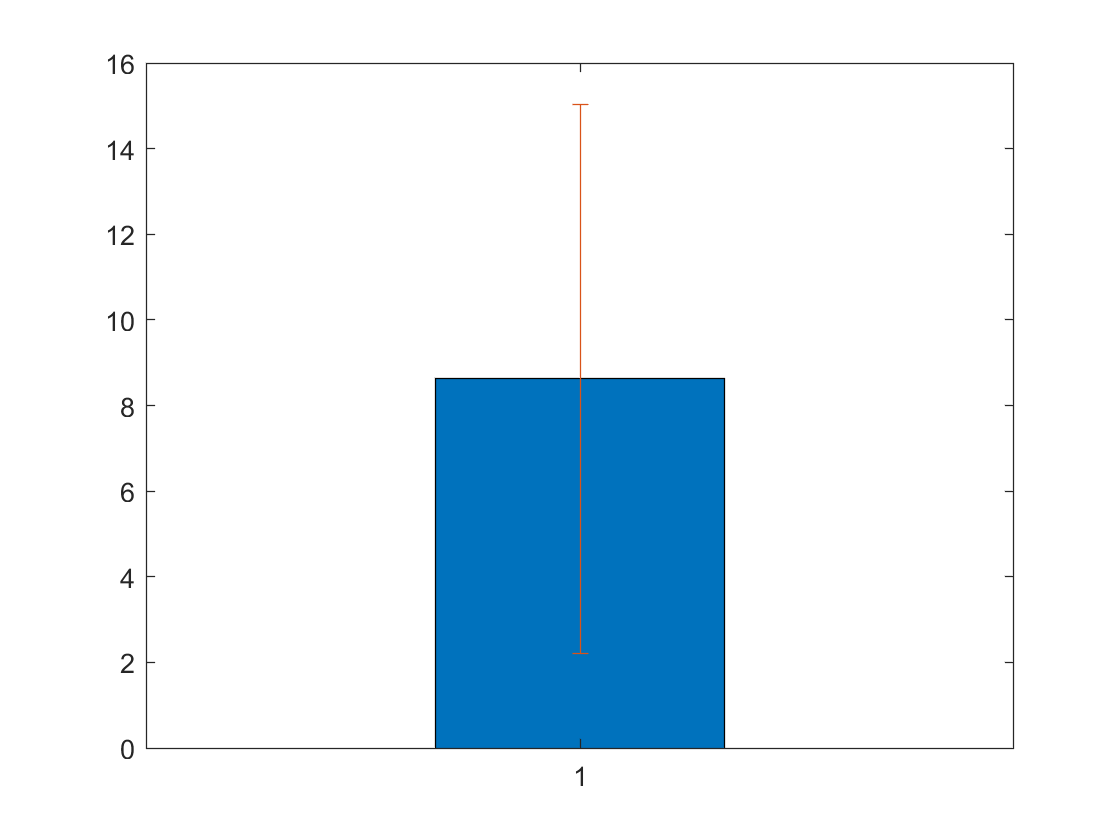

[h,p] = ttest(openarm) % This version is using a null hypothesis of mu=0

[h,p] = ttest(openarm,10) %null hypothesis of 50

50-mean(openarm) % Calculate the difference from our null hypothesis

hnormal = 0

pnormal = 0.5000

effectsize =(50-mean(openarm))./std(openarm) %cohen's d : a measure of effect size


hnormal = logical
   0


pnormal = 0.9604

#### Generate a figure/graph to illustrate your question.

ans = 41.3800

effectsize = 6.4639

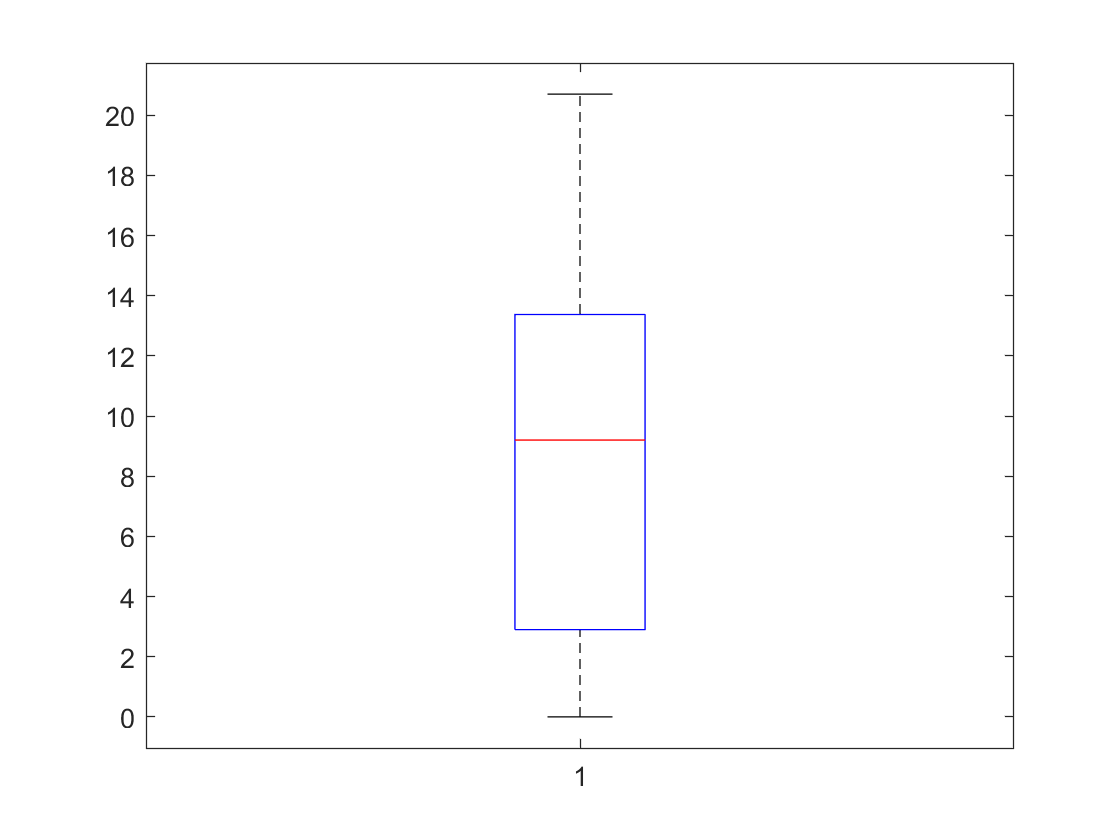

figure
boxplot(openarm)

#### Summarize your findings in words, referring to your statistical tests and measurements.  (If you want to get fancy, you can look up APA style for reporting statistical tests.)

t(df) = tval, p = 0.0000000000005

% add a little more about p-values and what they mean 

t-value and z-score 